# Evaluating Spectral Efficiency under UAV Antenna Misalignment

by Cesar Sanchez

**Introduction**

In this project, we take a look at how antenna beam misalignment impacts spectral efficiency in mmWave UAV communication links. In high frequency systems like 5G (especially around 28 GHz), directional beams are important for keeping a strong signal. But when the beam isn’t pointed quite within an optimal range, even by a few degrees the antenna gain and signal quality reduces significantly.

We will do the following:

- simulate what happens to spectral efficiency as alignment drifts, using Shannon’s formula

- visualize how antenna gain changes and how that affects clarity

- see how different Es/N0 levels react to misalignment

- demo a GUI that distorts an audio clip to sound like a misaligned link

- play a UAV animation that shows how drifting off axis hurts signal strength

**Why is this important?**

In UAV communication, especially at mm Wave frequencies, directional antennas play an important role in keeping a strong link over line of sight paths, but UAVs are almost always in motion. Slight tilts, enviromental disruptions, or falling off course get the antenna out of alignment. That kind of misalignment can lead to a noticeable drop in performance. Understanding how alignment affects the signal helps us:

- Design better tracking systems that can adapt quickly

- see how well a mmWave link holds up when the UAV isn’t perfectly stable

**Intro Simulation - SE vs Misallignment**

- Shows the theoretical SE degradation as alignment continuously worsens

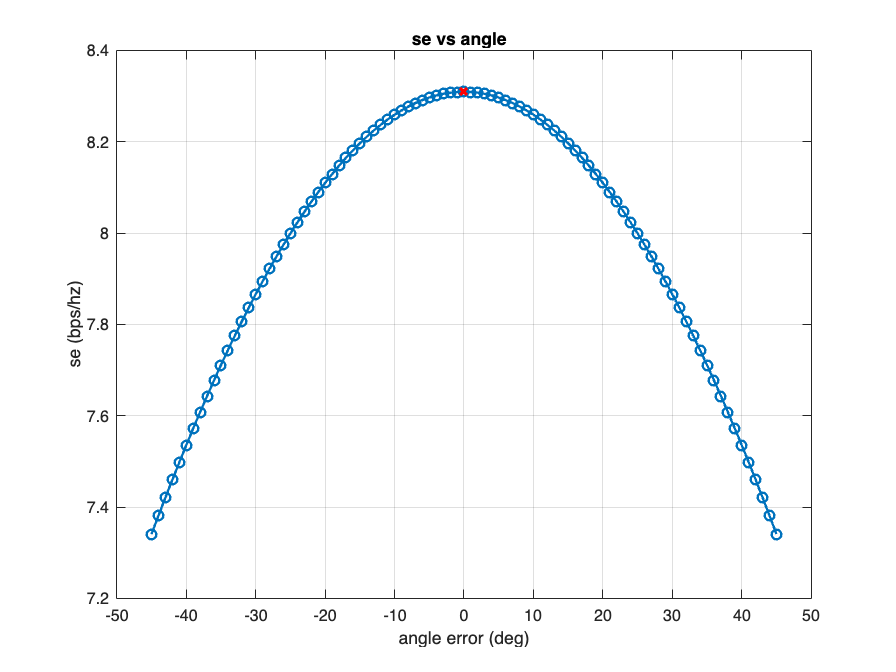

%% se vs alignment
% antenna gain drops if not aligned, snr drops, se drops

clear; clc

fc = 28e9;
c = physconst('LightSpeed');

lambda = c/fc;

ang = -45:1:45;   % angle err, degrees

gdb = 10 * cosd(ang);
gdb = max(gdb, -10);    % cut off floor

linG = 10.^(gdb / 10);   % to linear

peakdb = 15;
peak = 10^(peakdb / 10);

snr = peak * linG;
se = log2(1 + snr);    % shannon formula

figure
plot(ang, se, 'o-', 'LineWidth', 1.5)

xlabel('angle error (deg)')
ylabel('se (bps/hz)')

title('se vs angle  ')
grid on

[maxval, idx] = max(se);
hold on

plot(ang(idx), maxval, 'rx', 'LineWidth', 2)

%text(ang(idx), maxval+0.1, sprintf('max = %.2f', maxval))

thresh = maxval - 3;
id3 = find(se < thresh, 1);

if ~isempty(id3)
    fprintf('3db width about %d deg\n', abs(ang(id3)))
end

**Sweep Es/N0**

- Exploring SE at Different Es/N0 Levels

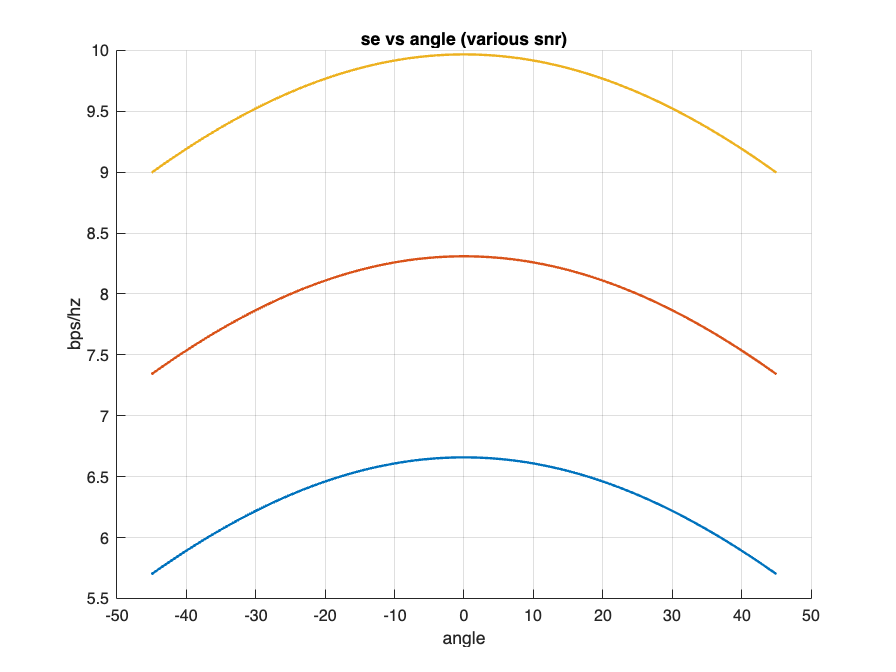

%% sweep snr values
vals = [10 15 20];

figure; hold on
for val = vals
    p = 10^(val / 10);
    g = p * linG;
    s = log2(1 + g);
    plot(ang, s, 'LineWidth', 1.5)
    %plot(ang, s, 'LineWidth', 2.5)
end

xlabel('angle');
ylabel('bps/hz');

title('se vs angle (various snr)');
grid on

This plot shows how beam misalignment affects spectral efficiency for different SNR levels. As the angle error gets bigger, SE drops, especially when the SNR is high.

**Radio Clarity Audio Demo**

A GUI that plays an audio clip where the quality changes based on the selected alignment angle, (controled by a gui knob).

- A GUI that plays an audio clip with quality degraded by alignment.

- As the antenna alignment drifts away from center (0 degrees, best connection), the audio becomes more distorted and it becomes harder to discern song lyrics.

- Simulates what poor link quality might sound like to a listener receiving the message

- Illustrates the real world effect of SNR loss

- Current file is named: justin_beiber_song.wav, substitute with any song of your choosing to see the same effect

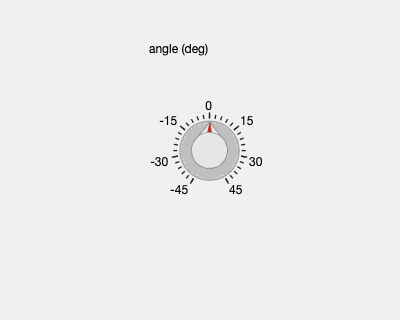

%% radio distortion gui
clear

%setTime = 20;

[x, fs] = audioread('justin_beiber_song.wav');

x = mean(x, 2);    % mono
x = x(1:min(end, fs*20));  % 20s

f = uifigure('Name', 'radio demo', 'Position', [100 100 400 320]);

uilabel(f, 'Text', 'angle (deg)', 'Position', [150 260 120 25]);

% degree staggaring
knob = uiknob(f, 'continuous', ...
    'Limits', [-45 45], 'MajorTicks', -45:15:45, ...
    'Position', [180 140 60 60], ...
    'ValueChangedFcn', @(src, evt) radioPlay(src.Value, fs, x));

- knob calls radioPlay func

% works
% plays radio simulation
function radioPlay(theta, fs, x)

    %c = max(0 , 1 - abs(theta)/45);  % linear

    c = max(0 , 1 - (abs(theta)/45)^2);  % clarity factor

    %fc = 300 + c * (fs/2 - 300);


    fc = 300 + c^3 * (fs/2 - 300);  % low pass cutoff

    d = designfilt('lowpassiir', 'FilterOrder', 8, ...
        'HalfPowerFrequency', fc, 'SampleRate', fs);

    %d = designfilt('lowpassiir','FilterOrder',4,...   
    %'HalfPowerFrequency',fc,'SampleRate',fs);

    y = filter(d, x);

    %nv = var(x)*(1-c)*2;
    nv = var(x)*(1-c)^2* 4;     %var x, base audio signal


    y = y + sqrt(nv) * randn(size(y));    % noise
    % y = y + sqrt(nv) * randn(size(y))

    if c < 0.4
        y = floor(y*128)/128;    % bit crush
    end

    y = y/max(abs(y)+1e-12);    % normalize

    persistent p
    
    if ~isempty(p) && isplaying(p)
        stop(p)
    end

    p = audioplayer(y, fs);
    play(p);

    fprintf('angle = %+d   clarity = %.2f\n', round(theta), c)

end

**UAV Visualization**

- Animates how a theoretical UAV drifting might change beam alignment and SE

- As the UAV moves, the visualization tracks its position on a curved beam arc, while updating the coresponding spectral efficiency

- NOTE: Toggle the plot to control for yourself

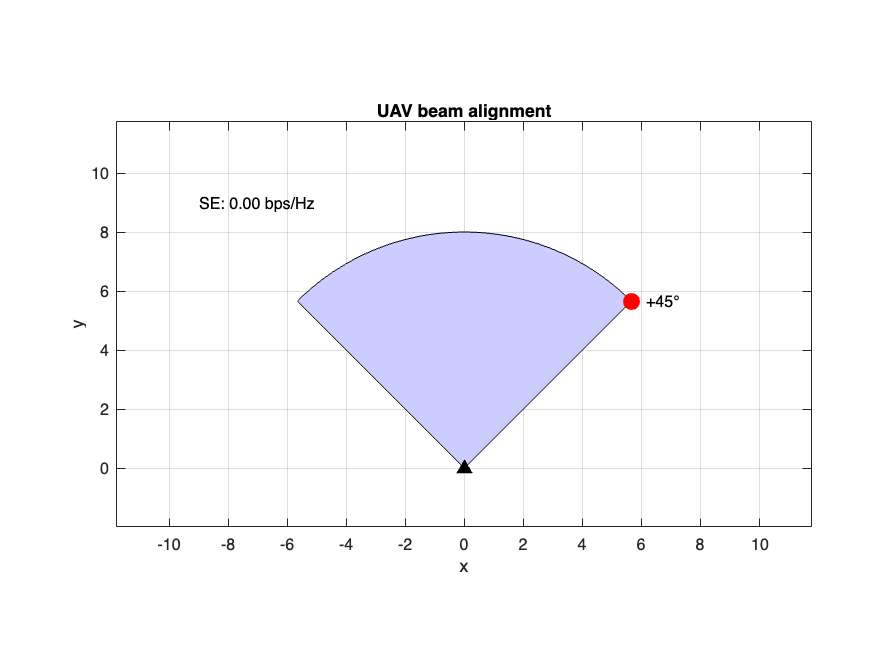

% uav visualization, 0 best, the farther it gets, worse

theta = -45:1:45;
clarity = max(0, 1 - (abs(theta)/45).^2);  %  alignment

figure;

for i = 1:length(theta)
    clf

    r = 8;  
    %r = 10;
    t = linspace(pi/2 - pi/4, pi/2 + pi/4, 100);   % arc facing up (centered at 90 dgrees)


    xb = [0, r*cos(t), 0];
    yb = [0, r*sin(t), 0];


    %t = linspace(-pi/4, pi/4, 100);         
    %r = 10;                   % beam radius
    %xb = [0, r*cos(t), 0];
    %yb = [0, r*sin(t), 0];

    fill(xb, yb, [0.8 0.8 1]); hold on

    % base station, denoted by a triangle shape
    plot(0, 0, 'k^', 'MarkerFaceColor', 'k', 'MarkerSize', 8)

    % plot UAV
    angleDeg = theta(i);

    x_uav = sind(angleDeg)*8;
    y_uav = cosd(angleDeg)*8;

    %plot(x_uav, y_uav, 'bo', 'MarkerFaceColor','b','MarkerSize',12)

    plot(x_uav, y_uav, 'ro', 'MarkerFaceColor','r','MarkerSize',10)

    text(x_uav+0.5, y_uav, sprintf('%+d°',angleDeg))

    % annotate SE
    se_val = log2(1 + clarity(i)*10);

    text(-9,9,sprintf('SE: %.2f bps/Hz', se_val), 'FontSize', 10)
    %text(-12,12,sprintf('SE: %.2f bps/Hz', se_val), 'FontSize', 10)

    axis equal
    axis([-12 12 -2 12]);

    title('UAV beam alignment')
    
    xlabel('x'); 
    ylabel('y');

    grid on

    pause(0.05)

end

## **Conclusion:**

#### **This project ultimately showed how even slight antenna misalignment can result in major drops in spectral efficiency. From our theoretical SE plots to audio and visual demos, we explored both the technical and simulated real world impacts of beam alignment. Exploring these issues are important because they can help improve telecommunications technology for future aerial communication.**

**My References:**

- [**https://tmytek.com/post/beam-steering-snr-phase-video**](https://tmytek.com/post/beam-steering-snr-phase-video)

- [**https://www.shure.com/en-US/insights/external-antennas-improve-signal-noise-ratio**](https://www.shure.com/en-US/insights/external-antennas-improve-signal-noise-ratio)

- [**https://www.mathworks.com/help/matlab/ref/matlab.ui.control.knob.html**](https://www.mathworks.com/help/matlab/ref/matlab.ui.control.knob.html)